# **Predicting the Outcome of a Tennis Match**

# Introduction

This project aims to train a model with the purpose of predicting the outcome of a hypothetical tennis match between two professional tennis players. A mathematical model is chosen and trained using data from previous tournaments and matches, and it is later used to make the predictions. Specifically, the model takes into account the odds generated by several gambling companies, and predicts the match outcome based on the odds that are presented to it. The model relies on logistic regression— a method that outputs a probability with the predicted outcome.

The game of tennis dates back to 12th century France, as believed by many historians, when it was called "jeu de paume" (literally "game of the palm). You simply used your hand. Over time the game evolved to include a leather glove, and finally a racket in the 16th century. That is also when the rules became unified. The name itself has its origins in the French phrase "tenez!" which means "hold" or "receive"— a call to the opponent who is about to receive the serve. The name was widely popularized, and that is where the modern "tennis*"* comes from [Wikipedia].

As with all sports, betting on tennis matches became a regular thing. The game and the betting became a package deal. Tennis is in fact one of the top five sports in the world, garnering billions of fans. According to "Why Tennis Betting Is So Popular," The tennis gambling market is enormous, currently generating billions of dollars each year in bets, being surpassed only by football. It also elaborates on why tennis is such a popular sport to bet on.

One reason is that it is essentially gambling due to the sport's unpredictability. Unlike other sports, tennis is individual, meaning that the outcome mostly rests in one player's hands. And humans are unpredictable. The second reason is because of "the sheer number of things you can bet on." As the *OddsMonkey Blog* outlines, there are endless markets to bet on. The list includes match betting, handicap betting, over and under totals, correct score, set winner, and so many more. There is a niche for everyone.

Tennis betting is extremely widespread and commonplace. And with a market currently sitting at billions of dollars, there is a lot to be gained from making a correct prediction. There is a reason after all, why tennis is subject to corruption and match tampering. The Davydenko incident of 2007 marvelously illustrates this point [Rios]. So of course, predicting the outcomes of tennis matches has, and always will be, one of the most important aspects of the tennis industry.

The link below offers Excel files that contain statistics for thousands upon thousands of games played in a variety of tournaments for both the ATP Men’s Tour (21 years of data) and WTA Women’s Tour (14 years of data). It includes the detailed breakdown of each match down to the set score, the date, the tournament, its location, the surface type, etc. It also includes betting odds on the winner and loser from sources like Bet365, Centrebet, Expekt, and Gamebookers among others. And that is the data the model will rely upon.

Statistics/data from: [http://www.tennis-data.co.uk/alldata.php](http://www.tennis-data.co.uk/alldata.php)

This report will introduce the mathematical model that was used, the CVX implementation of the solution that processes the data and trains the model, an analytical disuccsion of the results (the accuracy of the model), and concluding thoughts.

# Mathematical Model

### Logistic Regression

In order to output an accompanying probability with the decision of the model, logistic regression is used in order to construct the model. The input to this model are several feature values and the corresponding classification for that entry (1 or -1). This is a common and fundamental practice in optimization and artificial intelligence. For example, a spam filter works in a similar manner, classifying received emails as genuine content or just spam. The idea here is to separate the data into the loser and winner statistics. Each winner entry is classified as 1, while each loser entry is classified as -1.

The weight vector $\overrightarrow{\mathit{\mathbf{w}}}$ is assigned to the free parameter vector $\overrightarrow{\mathit{\mathbf{x}}}$, and the model attempts to best fit the model by adjusting the weights so as to increase the probability that the model correctly classifies each observed entry. This is called the *Principle of Maximum Likelihood*. In mathematical form, the model's objective (for each observation $j$) is the following;

### 
$$\max_w \;\prod_{j=1}^n P\left(y_j \left|x_j ,w\right.\right)$$


 If for example, the data contains the points $\left(x_1 ,1\right)$, $\left(x_2 ,1\right)$, $\left(x_3 ,-1\right)$, $\cdots$ , $\left(x_n ,-1\right)$, the goal of the model would be to maximize $P\left(1\left|x_1 ,w\right.\right)\cdot P\left(1\left|x_2 ,w\right.\right)\cdot P\left(-1\left|x_3 ,w\right.\right)\cdot \cdots \cdot P\left(-1\left|x_n ,w\right.\right)$. But how exactly will the probability of observing each data point be determined? In this case, the sigmoid functions will be used.

### Sigmoid Function

The sigmoid function has the form below, and it is graphed in the figure below.

### 
$$\Theta \left(s\right)=\frac{e^s }{1+e^s }=\frac{1}{1+e^{-s} }$$


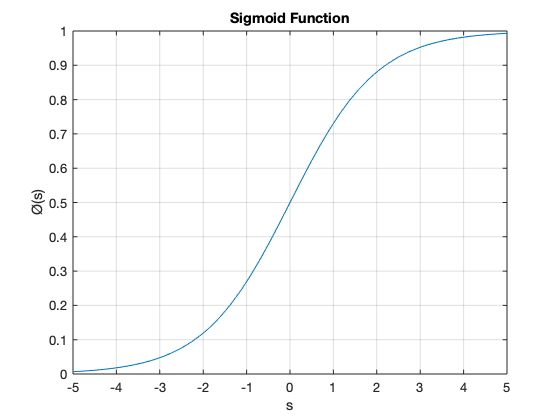

fplot(@(x) 1 / (1 + exp(-x)));
grid on
title('Sigmoid Function');
xlabel('s');
ylabel('Ø(s)');
ax = gca;
ax.FontSize = 13;

There are horizontal asymptotes at $\Theta \left(s\right)=1$ and $\Theta \left(s\right)=0$. In other words, $\lim_{s\to \infty } \;\Theta \left(s\right)=1$, and $\lim_{s\to \infty } \;\Theta \left(s\right)=1$. If the value of the function $\Theta \left(s\right)$ is $>0.5$, then the observation is classifed as 1. If it is $<0.5$, then the observation is classified as -1.

We define $h(x)$, the probability of $y=1$, as $\Theta \left(w^T \cdot x\right)$. A basic property in probability is that $P\left(A\right)=1-P\left(\bar{A} \right)$. So accordingly,$P(y=-1)=1-P(y=1)$, as 1 and -1 are the only two options. And finally we conclude $\Theta \left(z\right)=1-\Theta \left(-z\right)$ using the previous idea.

Now the goal of the model can be rewritten in terms of the sigmoid function. Again, if for example the data points are $\left(x_1 ,1\right)$, $\left(x_2 ,1\right)$, $\left(x_3 ,-1\right)$, $\cdots$ , $\left(x_n ,-1\right)$, the goal of the model would be to maximize the likelihood of observing that. Namely, maximizing $P\left(1\left|x_1 ,w\right.\right)\cdot P\left(1\left|x_2 ,w\right.\right)\cdot P\left(-1\left|x_3 ,w\right.\right)\cdot \cdots \cdot P\left(-1\left|x_n ,w\right.\right)$. The maximization problem from before can be rewritten as:

### 
$$\max_w \;\Theta \left({w^T \;x}_1 \right)\;\Theta \left({w^T \;x}_2 \right)\;\left(1-\Theta \left({w^T \;x}_3 \right)\right)\cdots \left(1-\Theta \left({w^T \;x}_n \right)\right)$$


### Convex Optimization Problem

All this leads to finally defining the convex optimization problem that we're solving. The problem with the current maximization problem is that it is not in standard convex form. Convex problems usually deal with minimizing an objective function. The following derivation finds an equivalent problem to solve.

### 
$$\max_w \;\prod_{j=1}^n P\left(y_j \left|x_j ,w\right.\right)$$


Maximizing a function is equivalent to maximizing the natural log of that function (and multiplied by a constant), so the following form is equivalent to the one before it.

### 
$$\max_w \;\frac{1}{n}\ln \left(\prod_{j=1}^n P\left(y_j \left|x_j ,w\right.\right)\right)$$


### 
$$\max_w \;\frac{1}{n}\sum_{j=1}^n \ln \left(P\left(y_j \left|x_j ,w\right.\right)\right)$$


### 
$$\max_w \;\frac{1}{n}\sum_{j=1}^n \ln \left(\Theta \left(y_j \;{w^T \;x}_j \right)\right)$$


Finally, maximizing a function is equivalent to minimizing the negative of that function, and so multiplying the previous form by -1  and minimizing that negative form yields the following expression.

### 
$$\min_w \;\frac{1}{n}\sum_{j=1}^n \ln \left(1+e^{-y_j \;{w^T \;x}_j } \right)$$


This final form is in fact the convex optimization problem written in standard form. The objective function is $\frac{1}{n}\sum_{j=1}^n \ln \left(1+e^{-y_j \;{w^T \;x}_j } \right)$, the decision variable is $w$, and there are no constraints.

### Batch Gradient Descent

Gradient descent will be used to solve this problem. Gradient descent is an iterative solution that finds the optimal solution, well, iteratively. The general form of the iterative approach is

### 
$$x_{k+1} =x_k +d_k {\;\alpha }_k$$


where

- $k\in Z_+$ is the iteration index

- $x_k$ is the current point

- $x_{k+1}$ is the next point

- $d_k \in R^n$ is the direction to move along

- $\alpha_k \in R_+$ is the step size at iteration $k$

There are multiple ways to choose each of the components. For this problem, our stopping criteria will simply be a fixed number of iterations. The step size will be diminishing, meaning that $\alpha_k \longrightarrow 0$ ($\alpha_k =$$1/k$, for example). The direction to move along will be steepest descent, or the negative gradient.

Batch gradient descent means that at every step of the descent process, the entire data set is used to calculate the direction to move along at the current point.

# Solution

### Pre-processing data

warning('off');

% data files
fileList = string(['2011.xlsx'; '2012.xlsx'; '2013.xlsx'; '2014.xlsx';
                   '2015.xlsx'; '2016.xlsx'; '2017.xlsx'; '2018.xlsx']);
files = size(fileList);

% placeholders
lose = [];
win = [];
xtrain = [];
ytrain = [];
xtest = [];
ytest = [];

% import data from all files in fileList
for i = 1:files
    
    import = readtable(fileList(i));
    tempW = [];
    tempL = [];
    
    % separate the winner's and loser's betting odds
    for j = 29:2:39
        
        % if-condition for column EXW being a string instead
        % instead of a double for some reason in 2013.xlsx
        if fileList(i) == "2013.xlsx" && j == 31
            tempW = [tempW, str2double(table2array(import(:, j)))];
            tempL = [tempL, table2array(import(:, j + 1))];
        else        
            tempW = [tempW, table2array(import(:, j))];
            tempL = [tempL, table2array(import(:, j + 1))];
        end
        
    end
    
    % concatenate the separated data
    win = [win; tempW];
    lose = [lose; tempL];
    
end

clear i j import tempW tempL;

% percentage of training data
pc = 0.65;

[total, params] = size(win);

% training data
xtrain = [win(1:ceil(total * pc), :); lose(1:ceil(total * pc), :)];
ytrain = [ones(ceil(total * pc), 1); -1 * ones(ceil(total * pc), 1)];

% testing data
% winTest and loseTest for later comparing actual match outcome
% AKA if the probability the loser wins is smaller than the probability
% the winner wins
xtest = [win(ceil(total * pc) + 1:total, :); lose(ceil(total * pc) + 1:total, :)];
winTest = win(ceil(total * pc) + 1:total, :);
loseTest = lose(ceil(total * pc) + 1:total, :);
ytest = [ones(total - ceil(total * pc), 1); -1 * ones(total - ceil(total * pc), 1)];

% "standardizing" the data leads to much better results
xtrain = xtrain * 10;
xtest = xtest * 10;
winTest = winTest * 10;
loseTest = loseTest * 10;

trainEntries = length(xtrain);
testEntries1 = length(xtest);
testEntries2 = length(winTest);

clear total win lose;

### Actual Problem

% intialize weights @ k = 0
w = zeros(params, 1);

% k = 2000 iterations
for k = 1:2000
    
    % diminishing step size
    step = 1 / k;
    
    % compute gradient
    grad = zeros(params, 1);
    for i = 1:trainEntries
        grad = grad + (ytrain(i) * xtrain(i, :) / (1 + exp(ytrain(i) * xtrain(i, :) * w)))';
    end
    grad = grad * (-1 / trainEntries);
    
    % iterate
    w = w - step * grad;
    
end

% GATHER TESTING ERROR

% individual classifications of whether the player
% is a loser or winner based on betting odds
correctWin = 0;
correctLoss = 0;
incorrectLoss = 0;
incorrectWin = 0;

% applying model to test dat
for i = 1:testEntries1
    prediction = 1 / (1 + exp(-1 * xtest(i, :) * w));
    if prediction >= 0.5 && ytest(i) == 1
        correctWin = correctWin + 1;
    elseif prediction < 0.5 && ytest(i) == -1
        correctLoss = correctLoss + 1;
    elseif prediction >= 0.5 && ytest(i) == -1
        incorrectLoss = incorrectLoss + 1;
    else
        incorrectWin = incorrectWin + 1;
    end
end

% overall accuracy of model
% seeing whether the probability the loser wins is smaller
% than the probability the winner wins
correct = 0;
wrong = 0;

for i = 1:testEntries2
    predictionWin = 1 / (1 + exp(-1 * winTest(i, :) * w));
    predictionLose = 1 / (1 + exp(-1 * loseTest(i, :) * w));
    if predictionWin >= predictionLose
        correct = correct + 1;
    else
        wrong = wrong + 1;
    end
end

clear i k step prediction predictionWin predictionLose;


% % convert table to string
% winners = table2array(winners);
% winners = string(winners);
% losers = table2array(losers);
% losers = string(losers);

# Results and Discussion

wins = correctWin + incorrectWin;
losses = correctLoss + incorrectLoss;

% output performance metrics
fprintf("Wins classified correctly = %.2f%%", correctWin / wins * 100);

Wins classified correctly = 71.63%

fprintf("Wins classified incorrectly = %.2f%%", incorrectWin / wins * 100);

Wins classified incorrectly = 28.37%


fprintf("Losses classified correctly = %.2f%%", correctLoss / losses * 100);

Losses classified correctly = 53.28%

fprintf("Losses classified incorrectly = %.2f%%", incorrectLoss / losses * 100);

Losses classified incorrectly = 46.72%


fprintf("Match outcomes classified correctly = %.2f%%", correct / testEntries2 * 100);

Match outcomes classified correctly = 64.53%

fprintf("Match outcomes classified incorrectly = %.2f%%", wrong / testEntries2 * 100);

Match outcomes classified incorrectly = 35.47%


clear correctwin correctLoss correct wrong incorrectWin incorrectLoss wins losses

The model is trained on 65% of the provided data– aptly named the training data– and then then applied as a test to the remaining 35%. The portion that is called the test data. As you can see, out of all the entries that were actually winning betting odds, the model classified 72% correctly. The other 28% the model classified as losses. And out of the entries that were actually losing betting odds, the model classified 53% correctly. That's still better than 50/50 chances.

Now, despite the fact that the model may recognize losing odds as winning odds, it may still decide that the probability of the winning odds being winning odds is still larger than the probability of the losing odds being winning odds. And because the purpose of the model is to predict the overall outcome of the match, it would still technically be correct in this case. That is what the third set of accuracies represents. For a match between two players, the model predicted the winner correctly 65% of the time. Not bad. Not great, either. I wouldn't trust this with my money. But still much better than a human can do.

The model appears to be pretty decent at recognizing winning odds, but not so great at recognizing losing odds. It's only slightly better at predicting losses than any human being. And it's doing okay at predicting the overall match outcome. Therefore, there are of course several issues with this model.

The first problem begins with the dataset itself. Some of it is missing, some of it is corrupt, some of it is unusable for other unknown reasons. The point is, this isn't data taken from the all-governing body of tennis. It's simply a website that collects statistics for anyone's use. There are bound to be problems. For example, as you can evidently see in the code, one of the parameters in *2013.xlsx* is for some reason entered as a `string` instead of a `double` like literally every other betting parameter. That of course wasn't a major issue, as it was luckily entirely `string`, so the workaround was simple. But still illustrates the point that the data could be unreliable.

A much more serious problem is one you nor I see (in its entirety, that is). Some information could simply be missing. The gravest issue I found was that in the data from *2010.xlsx*, a block of 942 entries for **two out of the six** betting parameters were simply empty. That's 942 out of 2680 entries. That's why 2010 wasn't included. And there are ones scattered amongst all the other files and entries that I just couldn't spot as easily. In order to be able to import and work with the data, I filled in the empty spaces with 0. These entries possibly contribute to the inaccuracy of the model.

The second problem is that the odds themselves never accurately reflect the probabilities of the match outcome. The odds are calculated in such a way that it profits the bookmaker. The bookmaers add what's called a "profit margin." That's why, as the famous saying goes, the house always wins [Shehryar].

Another problem is that betting odds are calculated not based on the pure skill of the competing players, like how significantly and how often they win matches. Instead, a "line" is made by the bookmaker after his/her analysis, and this line moves up or down (odds are adjusted) in order to balance the amount of money being put up on both sides. Once again, this is done in order to guarantee that the house receives a profit. So when a model uses these biased odds to make a prediction that should rely on skill and past performance, it's bound to be dodgy.

Finally, 6 parameters could potentially be a limiting factor to the model, not allowing it to be flexible enough.

However, this model produces overall decent results. Seeing as tennis betting is basically like playing the slot machines at casinos, being able to accurately predict even a little bit above 50% is an accomplishment. Once again, this is due to the fact that tennis is essentially gambling because of how unpredictable the outcome is. You never know how a player could be feeling that day. "Off days" are a common thing. And tennis is largely a mental game, requiring concentration throughout. And if a player just woke up on the wrong side of the bed, that's a huge factor not being accounted for in these betting odds.

# Conclusion

The model trained here seems to be decently accurate at recognizing when winning odds are indeed winning (an impressive 72%), but quite terrible at recognizing losing odds (only 53%). To reiterate, a 65% accuracy at predicting tennis match outcomes isn't ideal. It's very decent, considering the fact that tennis betting is basically gambling. But it is not a trustworthy predictor of a tennis match outcome, especially not when money is on the line. But surprisingly, 65% seems to be the expected trend.

In his M.S. dissertation, Joss Peters from the University of Edinburgh did an eerily similar project. However, this project featured multiple probabilistic models for predicting the outcome, one of which was the maximum likelihood model— practically identical to what was done here.

At the end of it all, Peters found that all the models– Match ML, Match Bayesian, Point ML, Point Bayesian, and many others— all yielded an accuracy that was **no more than 70%**. Clearly, predicting tennis match outcomes is a difficult science.

A possible direction to take this in the future is to run a model based purely on players' previous wins and losses. This model would use only skill to make its decision. The total number of games won could be accumulated for each player, and this data would be used to decide the outcome of the match.

# References

Peters, Joss. “Predicting the Outcomes of Professional Tennis Matches.” *University of Edinburgh*, 2017, [project-archive.inf.ed.ac.uk/msc/20172425/msc_proj.pdf.](http://project-archive.inf.ed.ac.uk/msc/20172425/msc_proj.pdf)

Rios, Tomas. “The Secret World of Tennis Gambling.” *The Daily Beast*, The Daily Beast Company, 5 July 2015, 12:01 AM ET, [www.thedailybeast.com/the-secret-world-of-tennis-gambling.](www.thedailybeast.com/the-secret-world-of-tennis-gambling.)

Sohail, Shehryar. “The Math Behind Betting Odds & Gambling.” *Investopedia*, Investopedia, 9 Feb. 2020, [www.investopedia.com/articles/dictionary/042215/understand-math-behind-betting-odds-gambling.asp.](www.investopedia.com/articles/dictionary/042215/understand-math-behind-betting-odds-gambling.asp.)

“Tennis Betting Markets: What to Bet on in Tennis.” *OddsMonkey Blog*, 25 May 2017, [www.oddsmonkey.com/blog/matched-betting/tennis-betting-markets/.](www.oddsmonkey.com/blog/matched-betting/tennis-betting-markets/.)

“Tennis.” *Wikipedia*, Wikimedia Foundation, 19 Mar. 2020, [en.wikipedia.org/wiki/Tennis.](http://en.wikipedia.org/wiki/Tennis)

“Why Tennis Betting Is So Popular.” *Last Word on Tennis*, 19 June 2019, [lastwordontennis.com/2019/06/19/tennis-betting-popular/.](http://lastwordontennis.com/2019/06/19/tennis-betting-popular)

***With special thanks to Professor Alizadeh, and whatever convinced her to extend the deadline for this report. Lord knows I needed it.***